% Declares variables
integers = 1:100000;
primeNums = primes(100)';
numPrimeAsFactors = linspace(0, 0, length(primeNums))';
factors = [2, 3, 5, 7, 11];

% Calls the function and stores the outputs in the two variables
[numPrimeAsFactors, numWithPrimeFactors] = primeAsFactors(primeNums, integers, numPrimeAsFactors, factors);

% Outputs the results of the function in a table and an array
table(primeNums, numPrimeAsFactors)

ans = 25×2 table
    primeNums    numPrimeAsFactors
    _________    _________________

        2              50000      
        3              33333      
        5              20000      
        7              14285      
       11               9090      
       13               7692      
       17               5882      
       19               5263      
       23               4347      
       29               3448      
       31               3225      
       37               2702      
       41               2439      
       43               2325      
       47               2127      
       53               1886      


disp(numWithPrimeFactors)

        2310        4620        6930        9240       11550       13860       16170       18480       20790       23100       25410       27720       30030       32340       34650       36960       39270       41580       43890       46200       48510       50820       53130       55440       57750       60060       62370       64680       66990       69300       71610       73920       76230       78540       80850       83160       85470       87780       90090       92400       94710       97020       99330



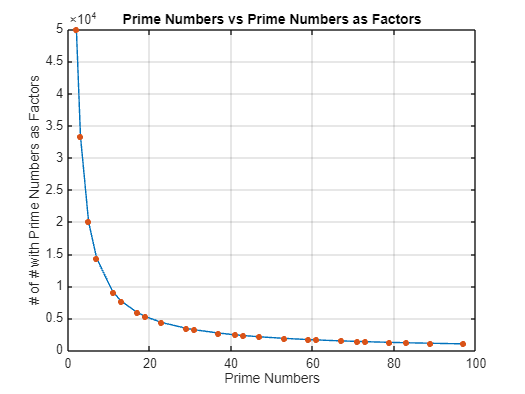


% Graphs the results of the function using plot()
figure
plot(primeNums, numPrimeAsFactors)
hold on
scatter(primeNums, numPrimeAsFactors, 25, "filled")
grid on;
title("Prime Numbers vs Prime Numbers as Factors");
xlabel("Prime Numbers");
ylabel("# of # with Prime Numbers as Factors");
hold off

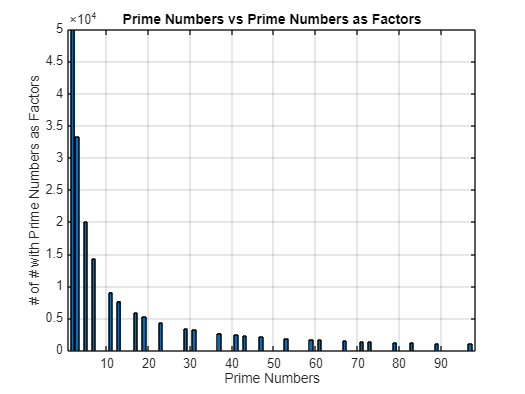


% Graphs the results of the function using bar()
bar(primeNums, numPrimeAsFactors)
grid on;
title("Prime Numbers vs Prime Numbers as Factors");
xlabel("Prime Numbers");
ylabel("# of # with Prime Numbers as Factors");
hold off


% Function that calculates numbers with primes as factors
function [outputPrimeAsFactors, numWithPrimeFactors] = primeAsFactors(primeNums, integers, numPrimeAsFactors, factors)
    % Declares local variables
    outputPrimeAsFactors = numPrimeAsFactors;
    numWithPrimeFactors = [];
    cond = 0;

    % Outer for loop which loops through the declared prime numbers
    for i = 1:length(primeNums)
        % Local variables as counters
        count = 0;

        % Inner for loop which loops through the declared integers
        for j = integers
            % Traverses through the integers array checking if they have
            % primes as factors
            if mod(integers(j), primeNums(i)) == 0
                % If true, then count for the number of primes as factors increases
                outputPrimeAsFactors(i) = outputPrimeAsFactors(i) + 1;
            end

            % Checks what integers have the array factors as factors
            if mod(integers(j), factors(1:length(factors))) == 0
                cond = 1; % Cond set to 1 like true for a boolean variable
                count = count + 1; % Count increases by 1
                numWithPrimeFactors(count) = integers(j); % The array at index 'count' is set to the integer which satisfies the factors
            end
        end
        
        % If cond is 1, then returns numWithPrimeFactors as an output of
        % the function
        if cond == 1
            numWithPrimeFactors;
        else
            % If no such integers found, then return 0
            numWithPrimeFactors = 0;
        end
    end
end